# Exercis 12

## 1. Inter-frame motion

% vid_1 = VideoReader('echo1.avi');
%optical_flow
opticFlow


With a really low threeholds vlue (for e.g : 0.00001), it also takes those small pixel into account when estimating the motion, thus resulting a lot of noise. 

## 2.Motion estimation in Echocardiography videos

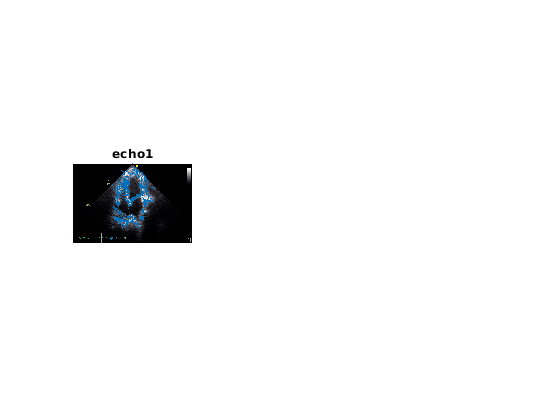

ec1 = VideoReader("echo1.avi");
ec2 = VideoReader("echo2.avi");



opticFlow = opticalFlowLK('NoiseThreshold', 0.01);

while hasFrame(ec1)
    % read the RGB frame
    ec1_frameRGB  = readFrame(ec1);

    % Convert rgb to grayscale
    ec1_frameGray = rgb2gray(ec1_frameRGB);
    %imshow(ec1_frameGray)
    
    % Compute optical flow
    flow = estimateFlow(opticFlow, ec1_frameGray);
    % Display rgb video frame with flow vectors
    subplot(1,3,1);
    imshow(ec1_frameRGB); title('echo1');
    hold on;
    plot(flow, 'DecimationFactor', [5 5], 'ScaleFactor', 10);
    drawnow;
    hold off;
end


while hasFrame(ec2)
    % read the RGB frame
    ec2_frameRGB  = readFrame(ec2);

    % Convert rgb to grayscale
    ec2_frameGray = rgb2gray(ec2_frameRGB);
    %imshow(ec1_frameGray)
    
    % Compute optical flow
    flow = estimateFlow(opticFlow, ec2_frameGray);
    % Display rgb video frame with flow vectors
    subplot(1,3,2);
    imshow(ec2_frameRGB); title('echo2');
    hold on;
    plot(flow, 'DecimationFactor', [5 5], 'ScaleFactor', 10);
    drawnow;
    hold off;
end


At some point the echo 2 of heart is really high (about 109 ) 

which is over 100 (normal limit people heart rate 60-100). 

Thus echo1 for heart 1 is heaithier.

The echo 2 signal on the bottom right is less regular compared to the echo 1 which is more stable.


%doc wiener2
% Object motion estimation using filtered grayscale.
ec2_e = VideoReader("echo2.avi");
opticFlow = opticalFlowLK('NoiseThreshold', 0.01);

while hasFrame(ec2_e)
     ec2_frameRGB  = readFrame(ec2_e);

    % Convert rgb to grayscale
    ec2_frameGray = rgb2gray(ec2_frameRGB);

    ec2_frameGray_fil = wiener2(ec2_frameGray,[7 7]);
    flow_fil = estimateFlow(opticFlow,ec2_frameGray_fil);
    subplot(1,3,3)
    imshow(ec2_frameRGB);title('echo2_fil')
    hold on;
    plot(flow_fil, 'DecimationFactor', [5 5], 'ScaleFactor', 10);
    drawnow;
    hold off;
end 
    
    